%********************************************************************************************
% Calculate the Lamberian Order M in different Angle
%********************************************************************************************
Angle = 0.1667*pi:0.01:0.5*pi;
Lam_Order = -log(2)./log(cos(Angle));
[hAx,hLine1,hLine2] = plotyy(Angle/pi*180,real(Lam_Order),Angle/pi*180,[cos(Angle).^2.5;cos(Angle).^1;cos(Angle).^0.5])

hAx =   1×2 Axes 数组:

    Axes    Axes


hLine1 =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×105 double]
              YData: [1×105 double]
              ZData: [1×0 double]

  显示 所有属性


hLine2 =   3×1 Line 数组:

  Line
  Line
  Line


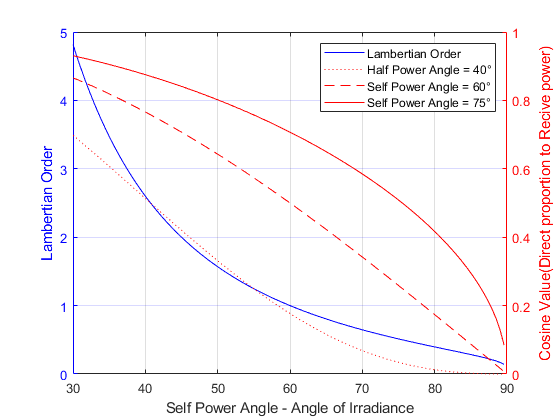

grid on 
set(hAx(1),'Ycolor','b')
set(hAx(2),'Ycolor','r')
set(hLine1,'linestyle','-','color','b');
set(hLine2(1),'linestyle',':','color','r');
set(hLine2(2),'linestyle','--','color','r');
set(hLine2(3),'linestyle','-','color','r');
xlabel('Self Power Angle - Angle of Irradiance')
ylabel(hAx(1),'Lambertian Order')
ylabel(hAx(2),'Cosine Value(Direct proportion to Recive power)')
legend('Lambertian Order','Half Power Angle = 40°','Self Power Angle = 60°','Self Power Angle = 75°')